clc;

clear;

trainingDS = imageDatastore('database', 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

numImages = 150;

trainingFeatures=[]


trainingFeatures =

     []



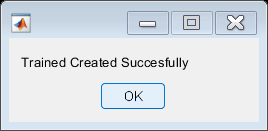


for i = 1:numImages

    img = readimage(trainingDS, i);

    trainingFeatures(i, :) =extractHOGFeatures(img, 'CellSize', [8 8]);

end

% Get labels for each image.

trainingLabels = trainingDS.Labels;

classifier = fitcecoc(trainingFeatures, trainingLabels);

save classifier classifier

%%%%%%%%%%%%%%%%%%%%%%%%%%

msgbox('Trained Created Succesfully');